# **AIR TRAFFIC MONITORING:**

## INTRODUCTION:

- Air traffic monitoring is crucial for modern aviation

- Needed to ensure safety and efficiency

- Automatic Dependent Surveillance-Broadcast (ADS-B) technology.

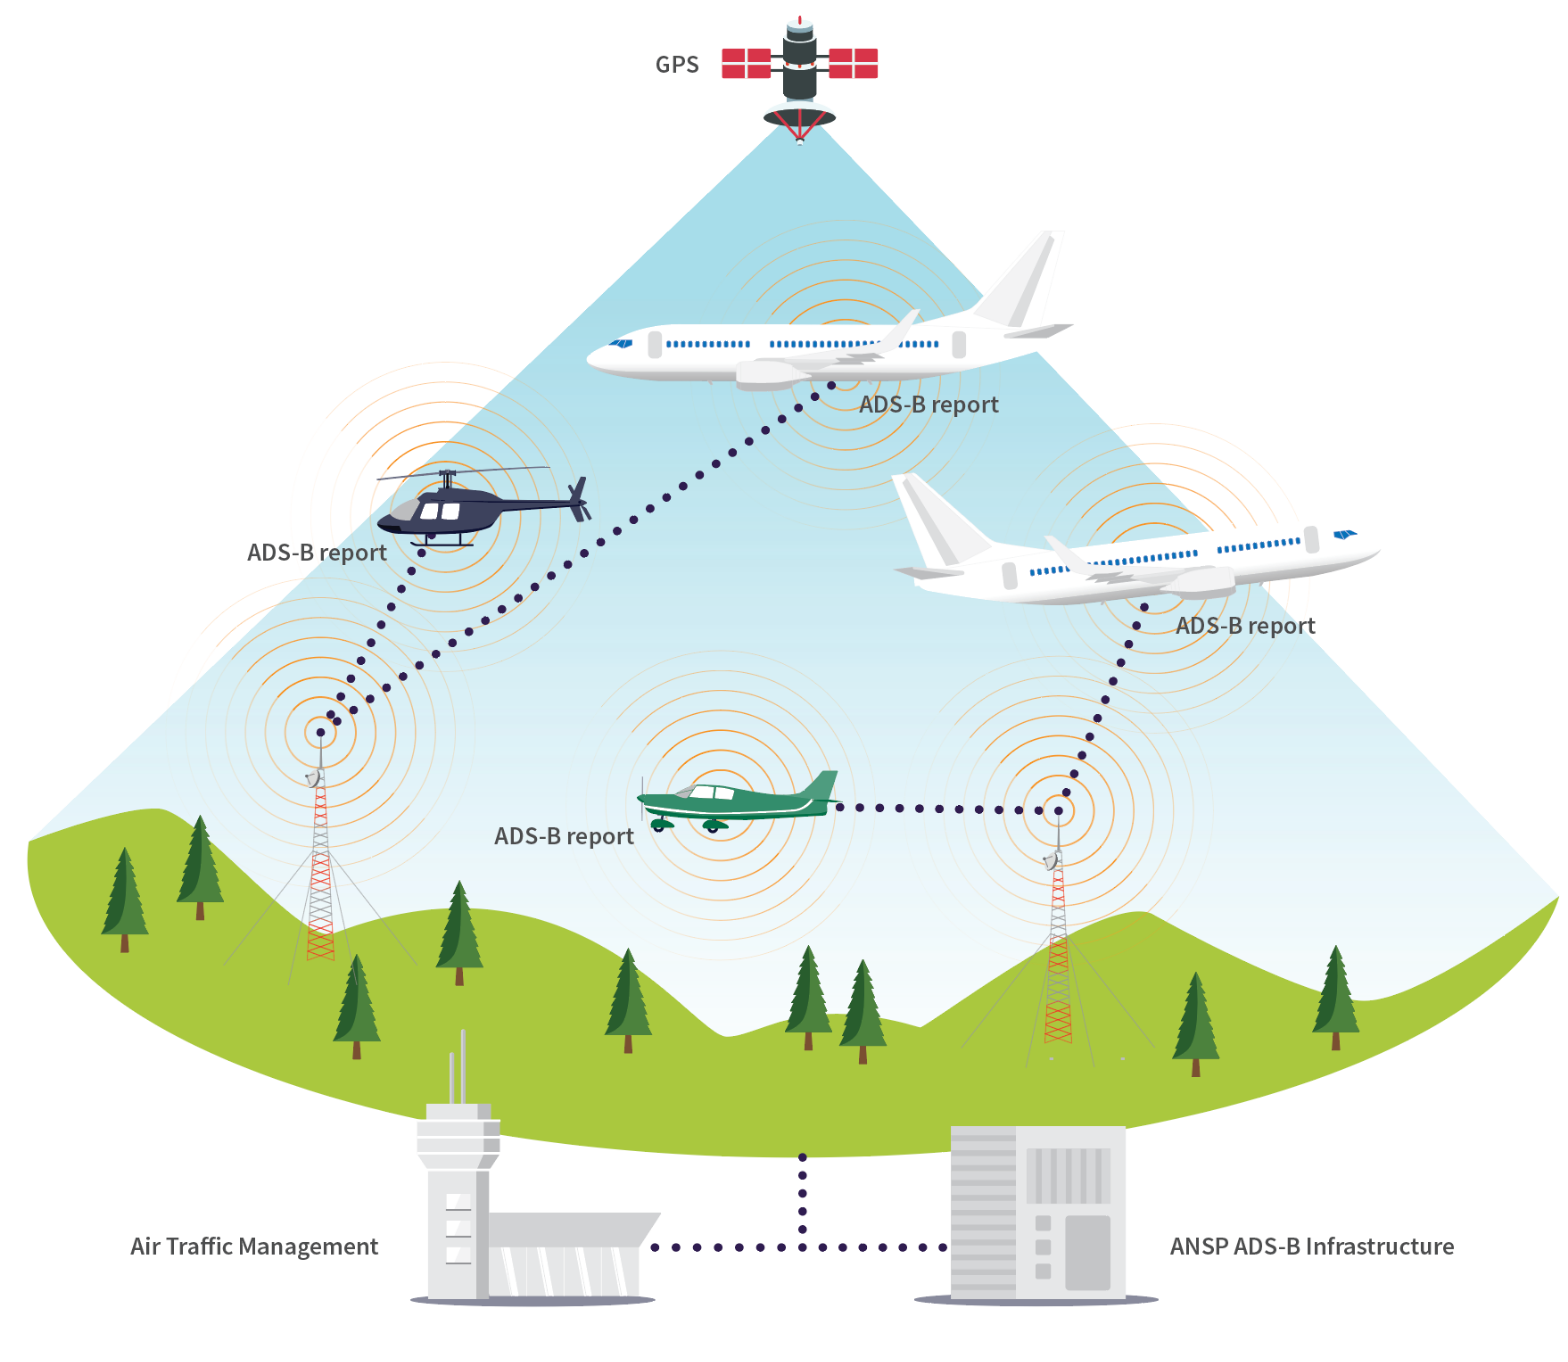

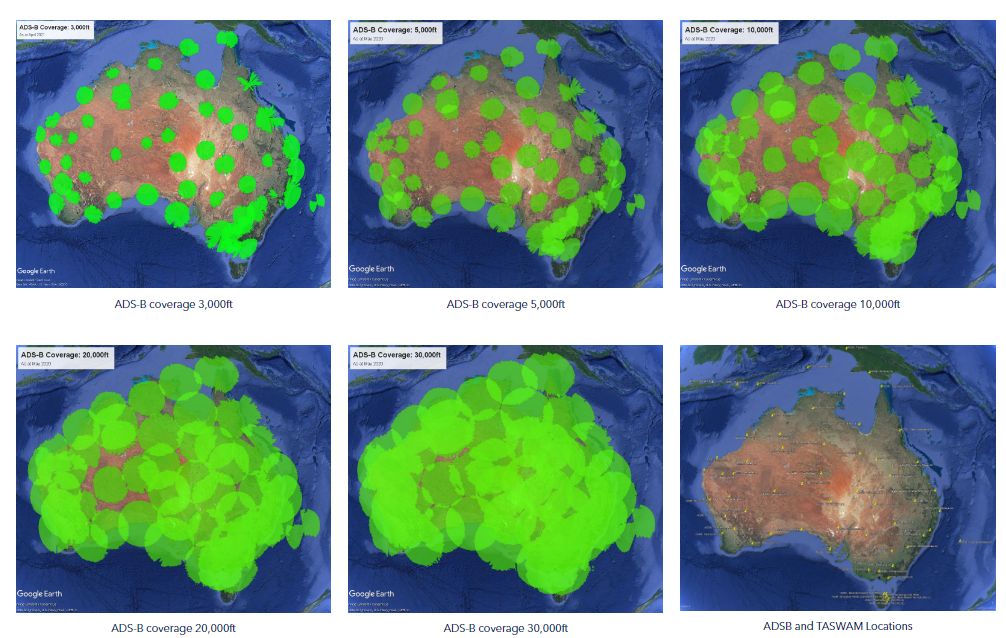

## PRINCIPLES:

- **Pulse Position Modulation and Demodulation**

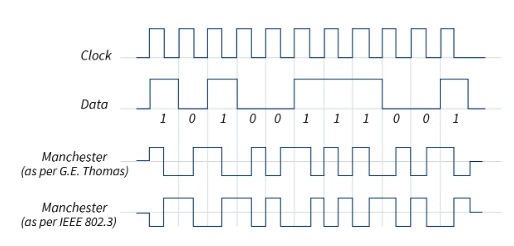

- **Amplitude Modulated and Demodulation**

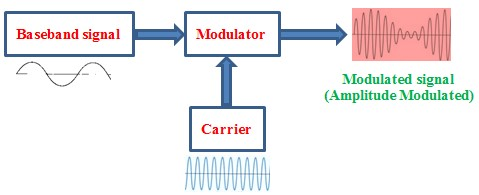

- **Preamble Detection and Symbol Detection**

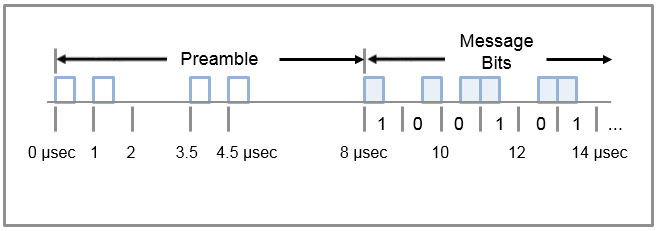

- **Parity Checking - Cyclic Redundancy Check (CRC-24)**

## DESIGN:

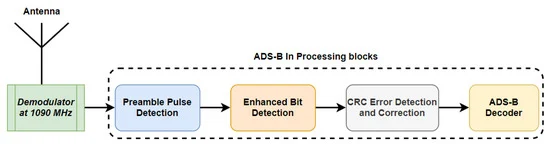

## IMPLEMENTATION:

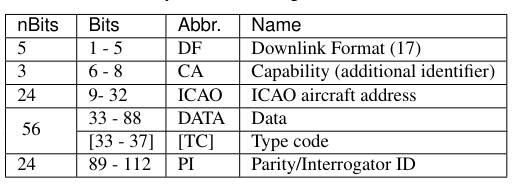

### `CAPTURED SIGNAL:`

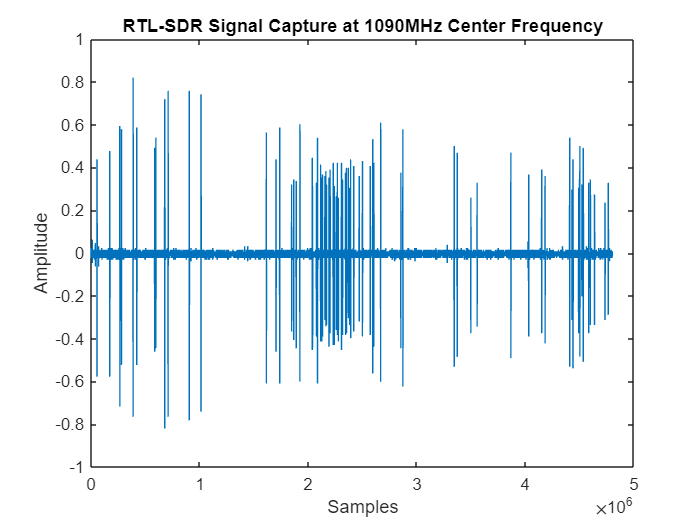

load('data/capturedData_5.mat', 'capturedData');
figure;
plot(real(capturedData));
ylabel('Amplitude');
xlabel('Samples');
title('RTL-SDR Signal Capture at 1090MHz Center Frequency');

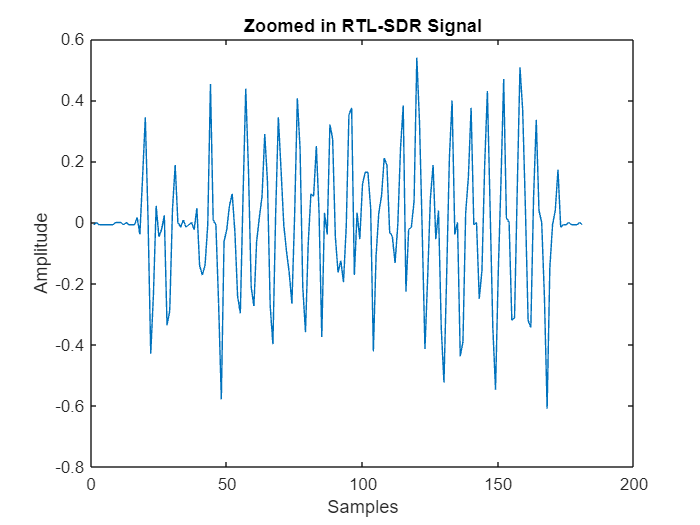

figure;
plot(real(capturedData(2085030:2085210)));
ylabel('Amplitude');
xlabel('Samples');
title('Zoomed in RTL-SDR Signal');

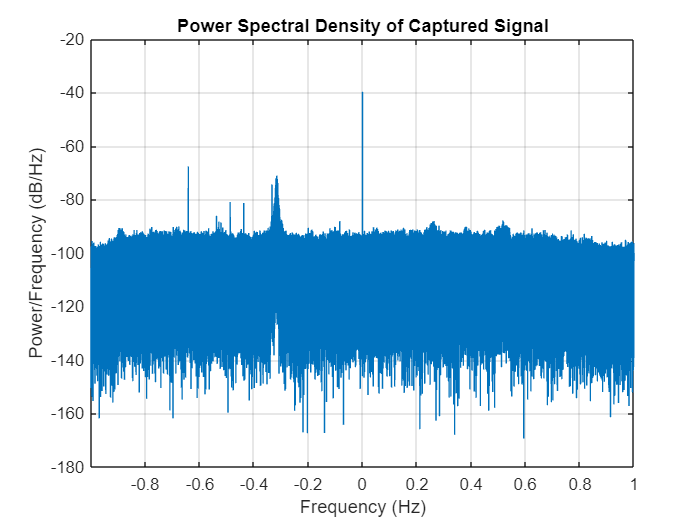

figure;
periodogram(capturedData, [], length(capturedData), 2e6, 'centered');
title('Power Spectral Density of Captured Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

### REAL TIME RTL-SDR 1090MHz Capture

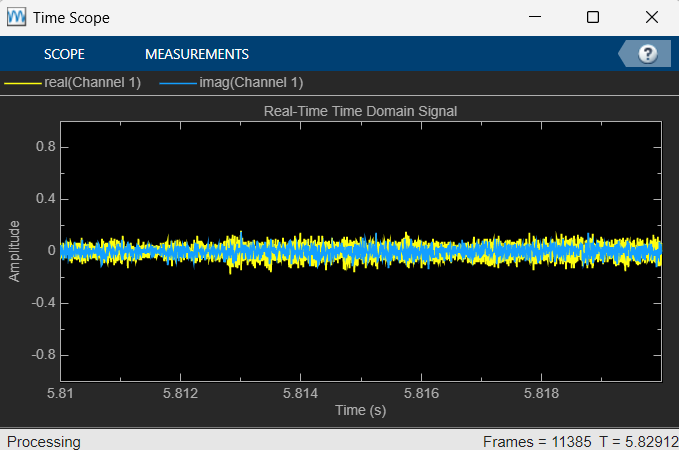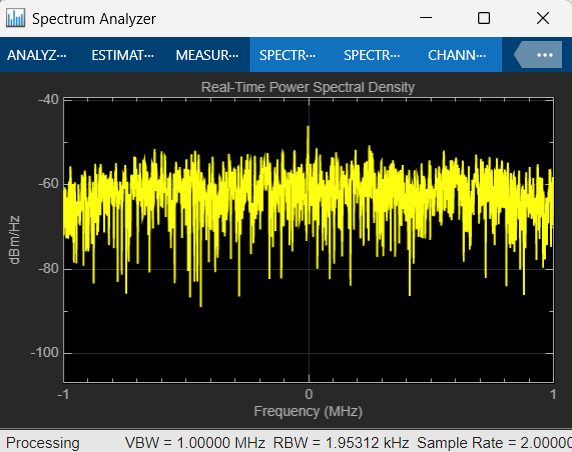   

## `SIMULATION:`

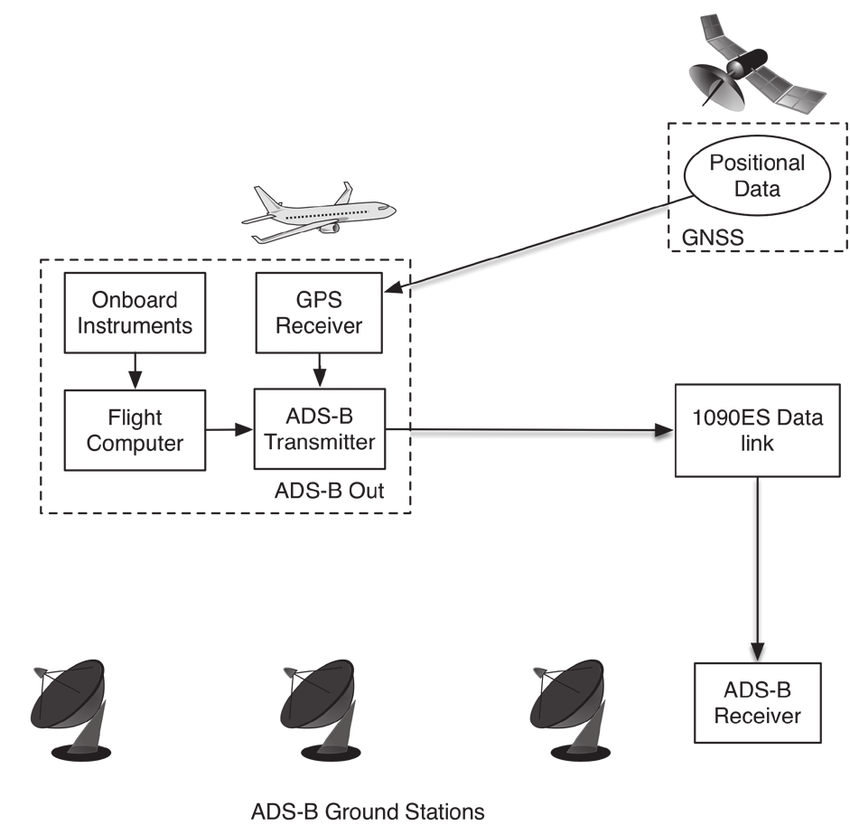

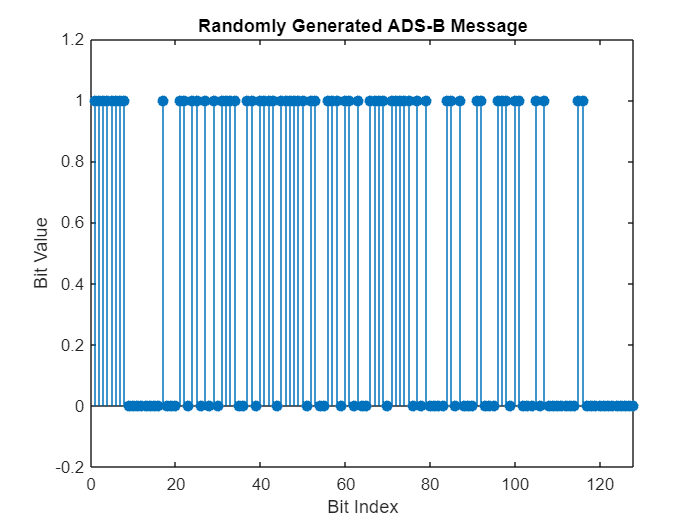

% Step 1: Create a realistic ADS-B message

fs = 20e6;
fc = 1090e6;
bit_duration = 1e-6;
pulse_duration = bit_duration / 2;
t = 0:1/fs:bit_duration-1/fs;

preamble = [ones(1, 8), zeros(1, 8)];
df = [1 0 0 0 1];
ca = [1 0 1];
icao = de2bi(hex2dec('ABCDEF'), 24, 'left-msb');
data = randi([0 1], 1, 56);
parity = de2bi(crc24([df ca icao data]), 24, 'left-msb');

message_bits = [df ca icao data parity];
message = [preamble message_bits];

figure;
stem(message, 'filled');
title('Randomly Generated ADS-B Message');
xlabel('Bit Index');
ylabel('Bit Value');
xlim([0 length(message)]);
ylim([-0.2 1.2]);

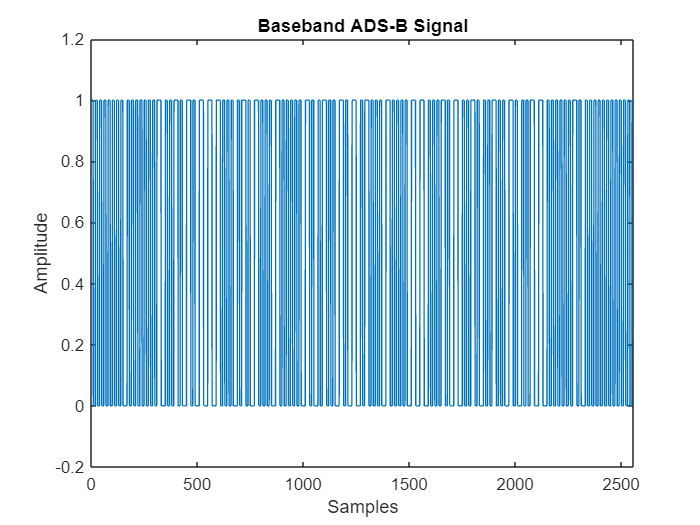


% Step 2: PPM Modulation
ppm_signal = [];
for bit = message
    if bit == 1
        pulse = [ones(1, length(t)/2), zeros(1, length(t)/2)];
    else
        pulse = [zeros(1, length(t)/2), ones(1, length(t)/2)];
    end
    ppm_signal = [ppm_signal pulse];
end

% Plot the PPM signal
figure;
plot(ppm_signal);
title('Baseband ADS-B Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([0 length(ppm_signal)]);
ylim([-0.2 1.2]);

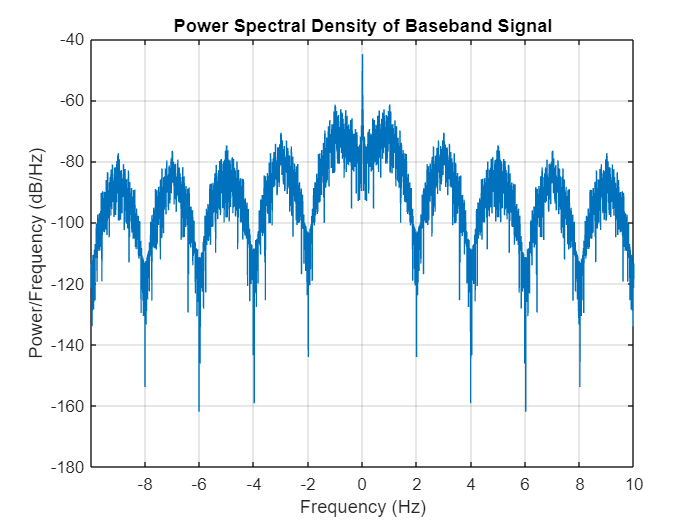

figure;
periodogram(ppm_signal, [], [], fs, 'centered');
title('Power Spectral Density of Baseband Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

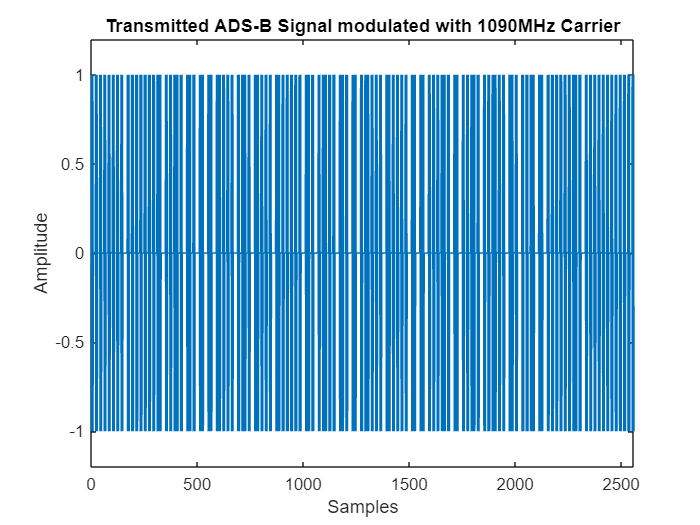


% Step 3: AM Modulation with Carrier
t_total = 0:1/fs:(length(ppm_signal)/fs) - 1/fs; % Total time vector
carrier = cos(2 * pi * fc * t_total); % Carrier signal
am_signal = ppm_signal .* carrier; % AM modulated signal

% Plot the AM modulated signal
figure;
plot(am_signal);
title('Transmitted ADS-B Signal modulated with 1090MHz Carrier');
xlabel('Samples');
ylabel('Amplitude');
xlim([0 length(am_signal)]);
ylim([-1.2 1.2]);

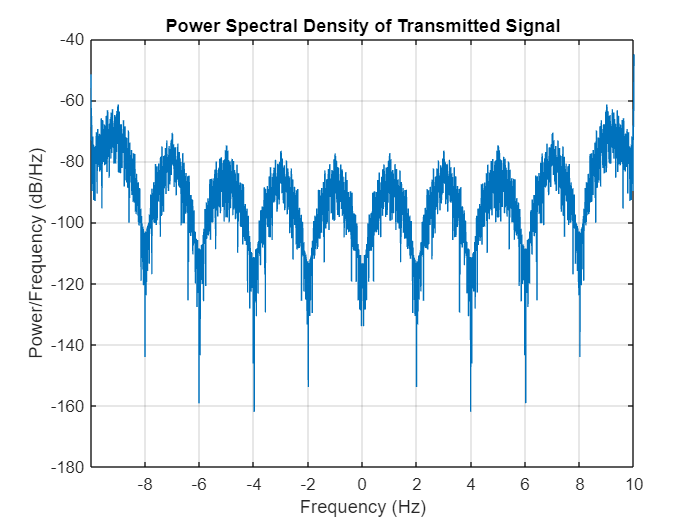

figure;
periodogram(am_signal, [], [], fs, 'centered');
title('Power Spectral Density of Transmitted Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

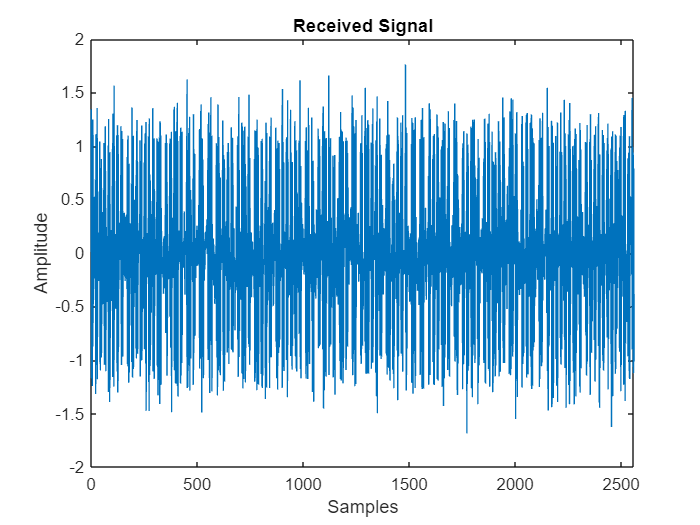


% Step 4: Transmission with Gaussian Noise
snr = 10;
received_signal = awgn(am_signal, snr, 'measured');

figure;
plot(received_signal);
title('Received Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([0 length(received_signal)]);figure;

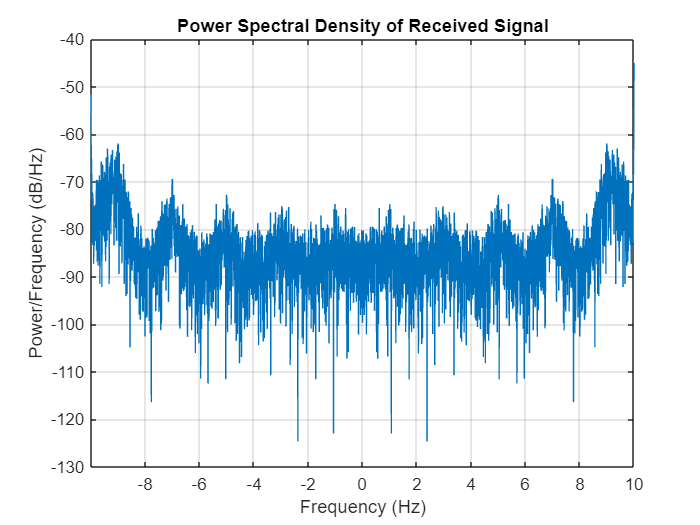

periodogram(received_signal, [], [], fs, 'centered');
title('Power Spectral Density of Received Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

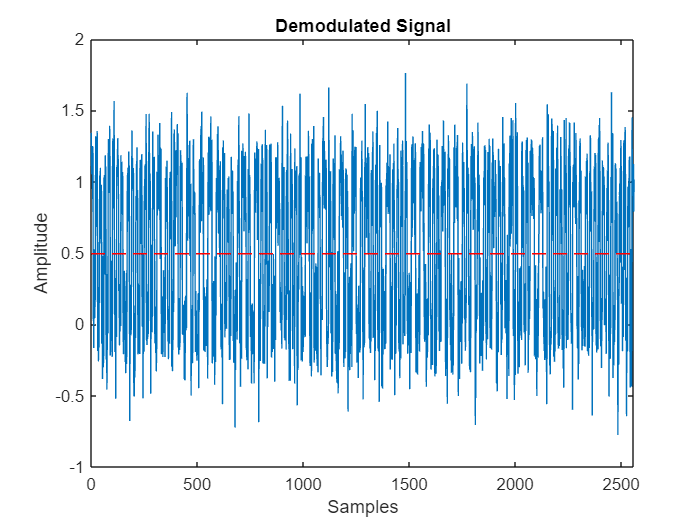

% Step 5: Demodulation
demod_signal = received_signal .* carrier;

threshold = mean(demod_signal);


figure;
plot(demod_signal);
hold on;
plot(threshold * ones(1, length(demod_signal)), '--r');
hold off;
title('Demodulated Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([0 length(demod_signal)]);

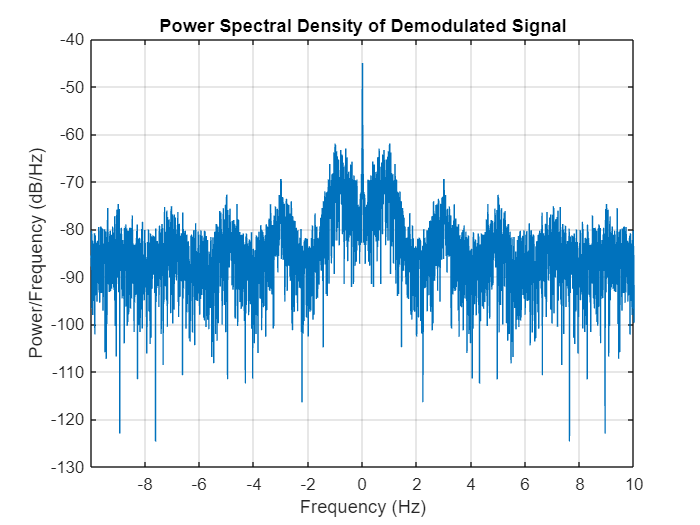

figure;
periodogram(demod_signal, [], [], fs, 'centered');
title('Power Spectral Density of Demodulated Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

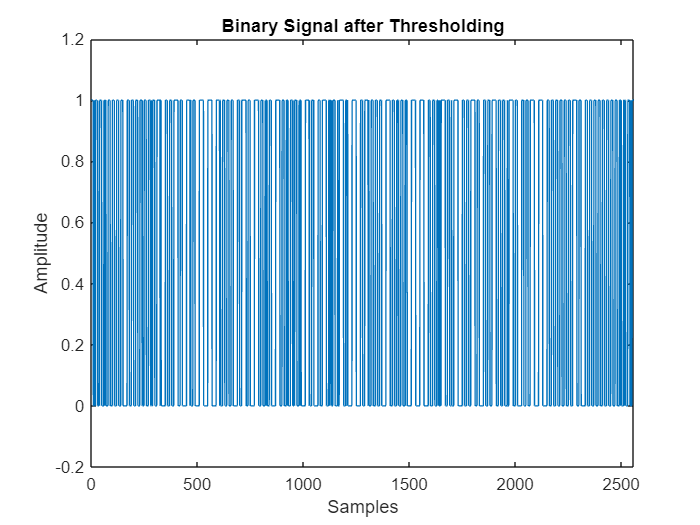

binary_signal = demod_signal > threshold;

figure;
plot(binary_signal);
title('Binary Signal after Thresholding');
xlabel('Samples');
ylabel('Amplitude');
xlim([0 length(binary_signal)]);
ylim([-0.2 1.2]);

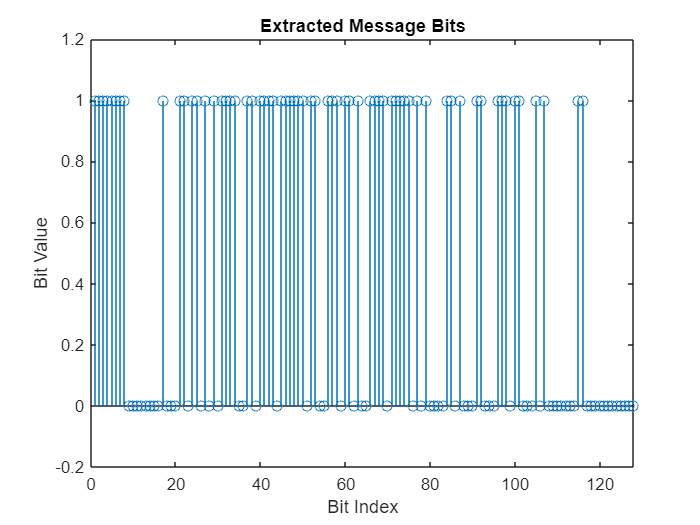

% Step 6: Extract and Verify the Message
extracted_message = [];
bit_samples = length(t);

for i = 1:bit_samples:length(binary_signal)
    bit_segment = binary_signal(i:i+bit_samples-1);
    if sum(bit_segment(1:bit_samples/2)) > sum(bit_segment(bit_samples/2 + 1: end))
        extracted_message = [extracted_message 1];
    else
        extracted_message = [extracted_message 0];
    end
end

figure;
stem(extracted_message);
title('Extracted Message Bits');
xlabel('Bit Index');
ylabel('Bit Value');
xlim([0 length(extracted_message)]);
ylim([-0.2 1.2]);

% Compare the extracted message with the original message
original_message = [preamble message_bits];
comparison = (extracted_message == original_message);
accuracy = sum(comparison) / length(original_message) * 100;

fprintf('Accuracy of the message extraction: %.2f%%\n', accuracy);

Accuracy of the message extraction: 100.00%


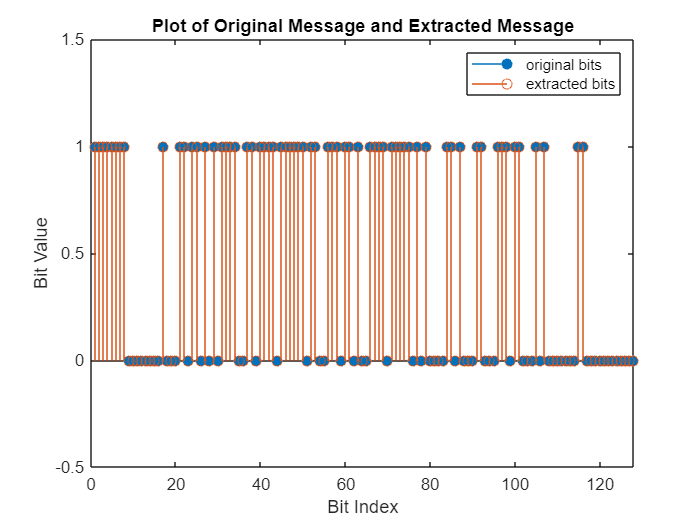

% Plot original message and extracted message bits for comparison
figure;
stem(original_message, 'filled');
hold on;
stem(extracted_message);
hold off;
legend('original bits', 'extracted bits');
title('Plot of Original Message and Extracted Message');
xlabel('Bit Index');
ylabel('Bit Value');
xlim([0 length(extracted_message)]);
ylim([-0.5 1.5]);

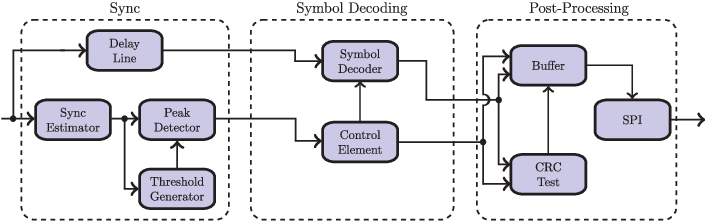

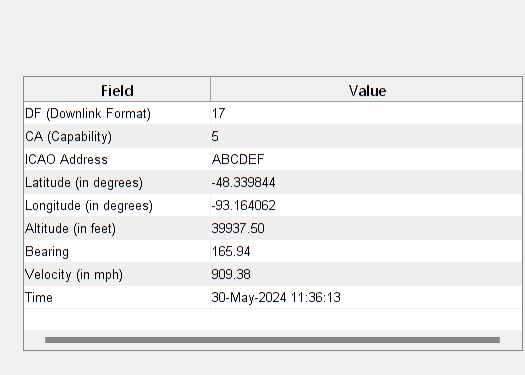

% Decoding the Extracted Message and Filling the Fields
adsb_decoder(extracted_message);

%adsb_decoder();

## CONCLUSION:

- ADS-B technology is significant in the field of Air Traffic Control

- Some risks involved, for e.g. privacy concerns, data overload.

- Benefits include enhanced safety, efficiency, broader coverage area, cost-effectiveness

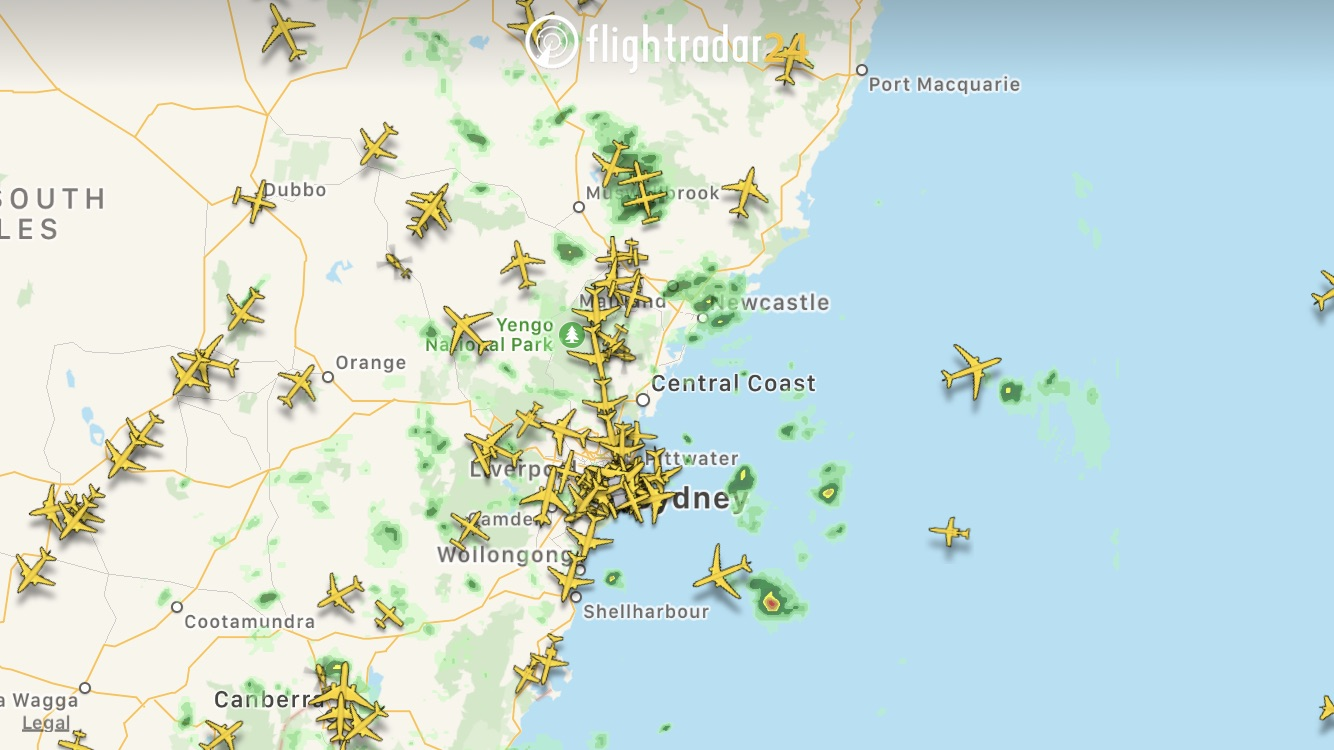

function adsb_decoder(extracted_message)

    % Arguments check to use the user provided extracted message or randomly generated message
    if nargin == 0
        preamble = [ones(1, 8), zeros(1, 8)];
        df = [1 0 0 0 1];
        ca = randi([0 1], 1, 3);
        icao = randi([0 1], 1, 24);
        data = randi([0 1], 1, 56);
        parity = de2bi(crc24([df ca icao data]), 24, 'left-msb');
        
        message_bits = [df ca icao data parity];
        extracted_message = [preamble message_bits];
    end

    % Decode the ADS-B message
    decodedMessage = decodeADSB(extracted_message);

    % Decode the data field
    decodedData = decodeDataFromADSB(decodedMessage.data);
    %decodedData = decodeDataFromADSB(randi([0 1], 1, 56));

    % Create a table to display the extracted information
    ADSB_Message = {
        'DF (Downlink Format)', num2str(decodedMessage.df);
        'CA (Capability)', num2str(decodedMessage.ca);
        'ICAO Address', dec2hex(decodedMessage.icao, 6);
        'Latitude (in degrees)', sprintf('%.6f', decodedData.latitude);
        'Longitude (in degrees)', sprintf('%.6f', decodedData.longitude);
        'Altitude (in feet)', sprintf('%.2f', decodedData.altitude);
        'Bearing', sprintf('%.2f', decodedData.bearing);
        'Velocity (in mph)', sprintf('%.2f', decodedData.velocity);
        'Time', decodedData.time
    };

    % Display the table in a GUI window
    figure('Name', 'Decoded ADS-B Message', 'NumberTitle', 'off');
    t = uitable('Data', ADSB_Message, 'ColumnName', {'Field', 'Value'}, ...
                'RowName', [], 'Position', [20 20 400 220]);
    t.ColumnWidth = {150, 250};  % Adjust column width
    
    % Adjust figure size to fit the table
    fig = gcf;
    fig.Position(3) = 420;  % Width
    fig.Position(4) = 300;  % Height

end

function decodedMessage = decodeADSB(message)
    % Constants
    preamble_length = 16;
    df_length = 5;
    ca_length = 3;
    icao_length = 24;
    data_length = 56;
    pi_length = 24;

    % Remove the preamble
    extracted_message_no_preamble = message(preamble_length + 1:end);

    % Extract DF, CA, ICAO, Data, and PI fields
    df_bits = extracted_message_no_preamble(1:df_length);
    ca_bits = extracted_message_no_preamble(df_length + 1:df_length + ca_length);
    icao_bits = extracted_message_no_preamble(df_length + ca_length + 1:df_length + ca_length + icao_length);
    data_bits = extracted_message_no_preamble(df_length + ca_length + icao_length + 1:df_length + ca_length + icao_length + data_length);
    pi_bits = extracted_message_no_preamble(df_length + ca_length + icao_length + data_length + 1:end);

    % Convert extracted fields to integers for readability
    decodedMessage.df = bi2de(df_bits, 'left-msb');
    decodedMessage.ca = bi2de(ca_bits, 'left-msb');
    decodedMessage.icao = bi2de(icao_bits, 'left-msb');
    decodedMessage.data = data_bits;
    decodedMessage.parity = bi2de(pi_bits, 'left-msb');
end

function decodedData = decodeDataFromADSB(data_bits)
    % This step depends on the specific content of the Data field.
    % I am defining the fields in a random manner, This is not the real
    % method of decoding ADS-B data.
    heading = ['N' 'NE' 'E' 'SE' 'S' 'SW' 'W' 'NW'];
    typeCode_bits = data_bits(1:5); % Assigning first 5 bits to Type Code
    latitude_bits = data_bits(6:15); % Assigning next 10 bits to latitude
    longitude_bits = data_bits(16:25); % Assigning next 10 bits for longitude
    altitude_bits = data_bits(26:35); % Assigning next 10 bits for altitude
    heading_bits = data_bits(36:38); % Assigning next 3 bits for heading
    velocity_bits = data_bits(39:46); % Assigning next 10 bits for velocity
    bearing_bits = data_bits(47:56); %Assigning the last 10 bits for bearing

    decodedData.typeCode = bi2de(typeCode_bits, 'left-msb');
    decodedData.latitude = bi2de(latitude_bits, 'left-msb') * (180 / (2^10)) - 90;
    decodedData.longitude = bi2de(longitude_bits, 'left-msb') * (360 / (2^10)) - 180;
    decodedData.altitude = bi2de(altitude_bits, 'left-msb') * (12000 / (2^10)) + 30000;
    decodedData.heading = heading(bi2de(heading_bits) + 1);
    decodedData.velocity = bi2de(velocity_bits, 'left-msb') * (200 / (2^8)) + 800;
    decodedData.time = datestr(datetime("now"));
    decodedData.bearing = bi2de(bearing_bits,'left-msb')*(360 / (2^10));
end


function crc = crc24(data)
    poly = hex2dec('864CFB'); % Polynomial for CRC-24
    crc = 0; % Initial value
    for bit = data
        crc = bitshift(crc, 1);
        if xor(bitshift(crc, -24), bit)
            crc = bitxor(crc, poly);
        end
    end
    crc = bitand(crc, hex2dec('FFFFFF')); % Mask to 24 bits
end
